# Radar Signal Processing Verification

This script has been written to confirm that the signal processing component of a radar is working as anticipated

## Initialize the simulator

clear;
simulator = Simulator_revB();
kristen_path = "C:\Users\krist\OneDrive\Documents\2022-2023 School Year\Radar Security Project\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
david_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
% file_path = "B210_params.json";
% file_path = "B210_params_highBW.json";
% file_path = "B210_params_highvres.json";
% file_path = "B210_params_lowBW.json";
% file_path = "B210_params_sensing_system.json";
% file_path = "X310_params_100MHzBW.json";
% file_path = "realistic_params.json";
file_path = "realistic_long_range.json";
simulator.load_params_from_JSON(david_path + file_path);


%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default attacker, and victim positions and velocities
simulator.load_realistic_attacker_and_victim_position_and_velocity();

%print out key parameters
simulator.Victim.print_chirp_parameters;

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 83.33 MHz/us
	 Idle Time: 			 1.16 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 85.33 MSps
	 Ramp End Time: 		 18.32 us
	 Chirp Tx Bandwidth: 		 1526.37 MHz
	 Chirp Sampling Bandwidth: 	 1000.00 MHz
	 ADC Sampling Period: 		 12.00 us
	 Chirp Cycle Time: 		 19.48 us
	 Chirp Wavelength: 		 3.89 mm



simulator.Victim.print_frame_parameters;

Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 4.99 ms


simulator.Victim.print_performance_specs;

Performance Specifications
	 Max Range 			 153.49 m
	 Range Resolution 		 0.15 m
	 Max Velocity 			 49.97 m/s
	 Velocity Resolution 		 0.39 m/s


simulator.Victim.print_FMCW_specs;

FMCW Specifications
	 FMCW sampling rate 		 1535.94 MHz
	 Downsampling factor 		 18
	 Sweep time 			 18.32 us
	 Samples per chirp 		 29916.00 


## Initialize the Target

simulator.load_target_realistic(25,-7);

## Initialize the Victim and Simulation Parameters

%specify the number of frames and chirps to compute
frames_to_compute = 10;

%specify whether or not to record a move of the range-doppler plot
record_movie = true;
simulator.Victim.Radar_Signal_Processor.configure_movie_capture(frames_to_compute,record_movie);

%pre-compute the victim's chirps
simulator.Victim.precompute_radar_chirps();

## Initialize the Attacker

%initialize the attacker parameters
simulator.Attacker.initialize_attacker(...
                        simulator.Victim.FMCW_sampling_rate_Hz * 1e-6,...
                        simulator.Victim.StartFrequency_GHz,...
                        simulator.Victim.Chirp_Tx_Bandwidth_MHz);

%initialize the sensing subsystem's debugger
simulator.Attacker.Subsystem_spectrum_sensing.initialize_debugger(1,simulator.Victim,frames_to_compute);

%initialize the attacker
simulator.Attacker.Subsystem_attacking.set_attacker_parameters(75,5,"target");

## Run the Simulation

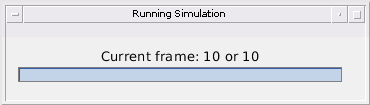

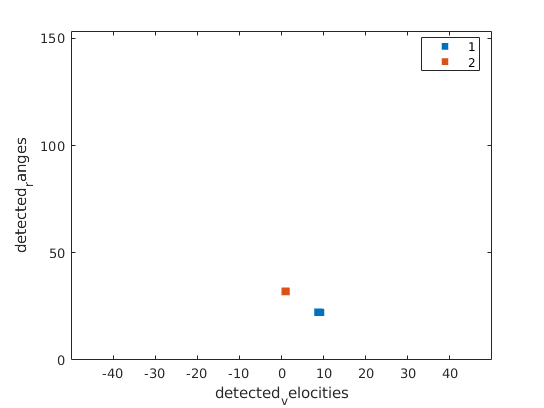

%run the simulation (without an attacker for now)
simulator.run_simulation_with_attack(frames_to_compute);

## Results

%get the estimated ranges and velocities
simulator.Victim.Radar_Signal_Processor.range_estimates

ans =    24.9852       NaN       NaN       NaN       NaN
   24.6966       NaN       NaN       NaN       NaN
   24.4050       NaN       NaN       NaN       NaN
   24.1104       NaN       NaN       NaN       NaN
   23.8097       NaN       NaN       NaN       NaN
   23.4974   74.7640       NaN       NaN       NaN
   23.1602   28.4547       NaN       NaN       NaN
   22.8288   30.0855       NaN       NaN       NaN
   22.5231   31.3451       NaN       NaN       NaN
   22.2265   32.0357       NaN       NaN       NaN


simulator.Victim.Radar_Signal_Processor.velocity_estimates

ans =     8.9813       NaN       NaN       NaN       NaN
    8.9801       NaN       NaN       NaN       NaN
    8.9758       NaN       NaN       NaN       NaN
    8.9687       NaN       NaN       NaN       NaN
    8.9571       NaN       NaN       NaN       NaN
    8.9416    1.0014       NaN       NaN       NaN
    8.9250    1.0056       NaN       NaN       NaN
    8.9541    1.0078       NaN       NaN       NaN
    8.9666    0.9976       NaN       NaN       NaN
    8.9750    1.0060       NaN       NaN       NaN


%play the movie for the range doppler
if record_movie
    simulator.Victim.Radar_Signal_Processor.play_range_doppler_movie();
end

%play the movie for the clusters
if record_movie
    simulator.Victim.Radar_Signal_Processor.play_clustering_movie()
end